# Virtual Theremin

#### Create Figure Window

fig = uifigure("Name", "Theremin", "Visible", "on", "interruptible", "off", "BusyAction", "cancel", "Resize", "off", "Position", [100 100 500 500]);
im = uiimage(fig)

im =   Image with properties:

        ImageSource: ''
        ScaleMethod: 'fit'
                URL: ''
    ImageClickedFcn: ''
           Position: [100 100 100 100]

  Show all properties


im.ImageSource= "/MATLAB Drive/Mathworks Stuff/i01_download-2.png"

im =   Image with properties:

        ImageSource: '/MATLAB Drive/Mathworks Stuff/i01_download-2.png'
        ScaleMethod: 'fit'
                URL: ''
    ImageClickedFcn: ''
           Position: [100 100 100 100]

  Show all properties


im.ScaleMethod = 'fill'

im =   Image with properties:

        ImageSource: '/MATLAB Drive/Mathworks Stuff/i01_download-2.png'
        ScaleMethod: 'fill'
                URL: ''
    ImageClickedFcn: ''
           Position: [100 100 100 100]

  Show all properties


im.Position = [0,0,500,500]

im =   Image with properties:

        ImageSource: '/MATLAB Drive/Mathworks Stuff/i01_download-2.png'
        ScaleMethod: 'fill'
                URL: ''
    ImageClickedFcn: ''
           Position: [0 0 500 500]

  Show all properties


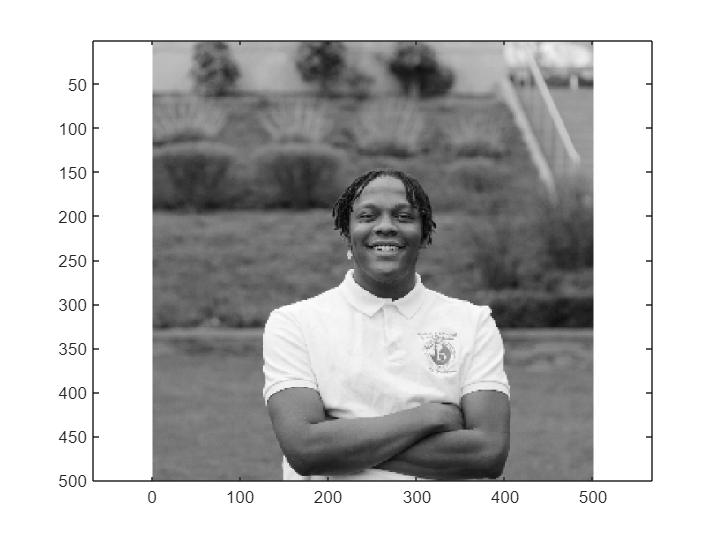

X = imread("i01_download-2.png");

grayscaleX = 0.2989*X(:,:,1) + 0.5870*X(:,:,2) + 0.1140*X(:,:,3);

imagesc(grayscaleX); colormap('gray'); axis equal

y = grayscaleX(347, 142)

y = uint8
236

#### Assign callback function property of figure

fig.WindowButtonDownFcn = @Pointer_Moved

fig =   Figure (Theremin) with properties:

      Number: []
        Name: 'Theremin'
       Color: [1 1 1]
    Position: [100 100 500 500]
       Units: 'pixels'

  Show all properties


#### Create the callback function

function Pointer_Moved(source, event)

X = imread("i01_download-2.png");

grayscaleX = 0.2989*X(:,:,1) + 0.5870*X(:,:,2) + 0.1140*X(:,:,3);

pos = source.CurrentPoint

x = pos(1);
y = pos(2);

color = grayscaleX(x,y)

pause(.001);

t = 0.2;

if (color >= 0 && color < 43)
    sineSound(110, t);
    
elseif(color >= 43 && color < 86)
    sineSound(220, t);  
elseif(color >= 86 && color < 128)
    sineSound(330, t);  
elseif(color >= 128 && color < 170)
    sineSound(440, t);  
elseif(color >= 170 && color < 213)
    sineSound(550, t);      
else
    sineSound(660, t);
end


end


© COPYRIGHT 2018-2019 by The MathWorks, Inc.